# Projetos no domínio da frequência 

## Projeto do controlador avanço-atraso 

Este live script visa apresentar e discutir os projetos de compensadores avanço e atraso de fase, avaliando-os em simulação. 

## **Definição do modelo e especificações de projeto**. 

Seja a FT de MA $G(s)=\frac{K}{(1+T_1s)(1+T_2s)}$, assumindo os parâmetros abaixo: 

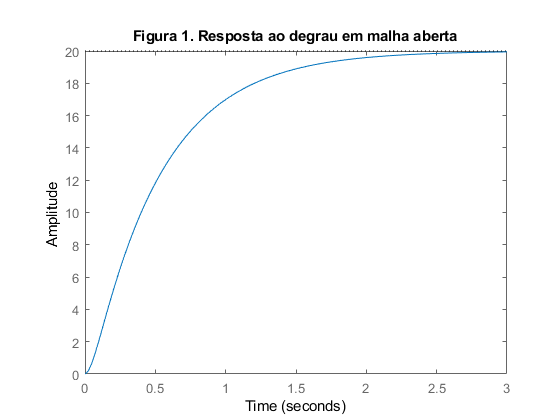

K=20;
T1=0.5;
T2=0.05;
G=tf(K,conv([T1 1],[T2 1]));
figure;step(G);
title('Figura 1. Resposta ao degrau em malha aberta');

Especificações de projeto:

Erro em regime $\le$1%

Tempo de estabelecimento $\le$1 segundo.

Sobreelevação $\le$4%, o que corresponde a $\zeta\geq 0.7$.

A resposta deste modelo será dada pelo modelo de referência $M(s)=\frac{\omega_n^2}{s^2+2\zeta\omega_ns+\omega_n^2}=\frac{32.6}{s^2+8.96s+32.6}$

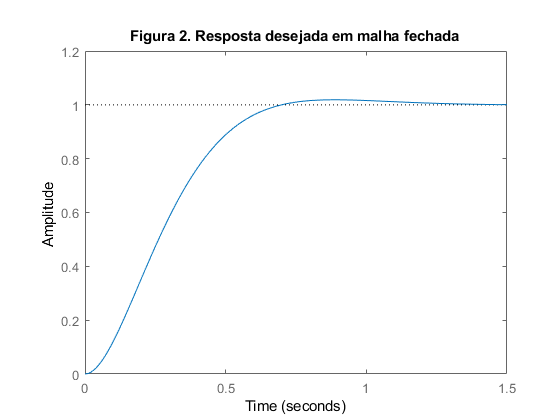

UPe=4;
tse=1;
M=tf(32.6,[1 8.96 32.6]);
figure;step(M);
title('Figura 2. Resposta desejada em malha fechada');

Como o modelo é tipo 1 e os compensadores avanço e atraso não têm polo na origem (como o PI), deve-se obter um ganho para atender o erro em regime. Esse ganho também deve conseguir uma resposta rápida.

Como o erro em regime é dado por $E=\frac{1}{K_cK}$, onde $K$é o ganho de G(s), obtemos o ganho do controlador $K_c$ de 

Kc=1/(K*0.01)

Kc = 5

 IMPORTANTE: talvez esse ganho garante o erro em regime especificado, mas talvez precise ser aumentado para atender ao  tempo de estabelecimento especificado ts.

Observe abaixo o gráfico de Bode de $G(s)$ e de $K_cG(s)$. 

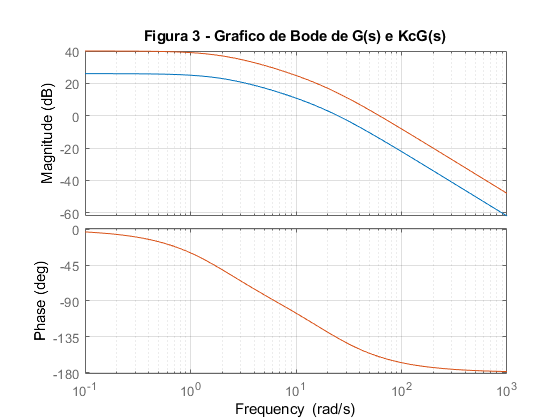

figure
bode(G,Kc*G);
title('Figura 3 - Grafico de Bode de G(s) e KcG(s)');grid

A margem de fase de G(s) é 43 graus, sendo reduzida para 19 graus com a adição do ganho Kc. 

O gráfico de bode com o ganho Kc é agora utilizado para o projeto dos compensadores.

## **Projeto do compensador atraso**

O compensador é dado por $C(s)=\frac{1}{a}\frac{1+aTs}{1+Ts}$, como $a<1$. 

Como o polo está em uma frequência mais baixa, $s=-1/T$, ele atrasa a fase antes que o zero em $s=-1/aT$ avance a fase.

Para aumentar a margem de fase, a curva de módulo deve ser reduzida de forma que cruze em 0dB na frequência onde a margem de fase seja a desejada. 

O projeto do compensador atraso é mostrado na figura abaixo, para $a=0.1$ e $T=100$. 

Usa-se o gráfico de Bode de malha aberta de Kc*g2 mostrado na Figura 3 para ver quanto o módulo deve ser reduzido.

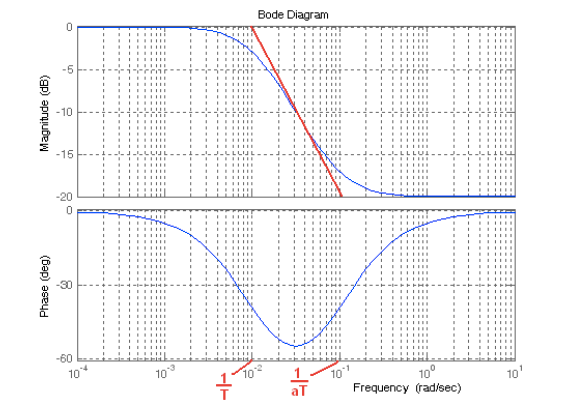

O ganho começa com 0dB e atinge o máximo de - 20dB. O valor mínimo da fase do controlador é -55 . 				

O zero do controlador está em 1/aT=0.1rad/s. O polo está em 1/T=0.01rad/s. O ganho começa a diminuir 20dB/dec a partir de 0.01rad/s (gráfico assintótico). 

Nesta mesma frequência a fase já diminuiu 45 graus. 					

Em aproximadamente 0.1rad/s (polo) a inclinação da curva de módulo passa a ser 0, e a fase continua em -45graus, devido à fase somada pelo zero e subtraída pelo polo. 

Uma década após o polo (1rad/s), a fase volta a ser 0 graus e o módulo se mantém em -20dB. 

Um menor valor de **a** faz a curva de módulo diminuir, aumentando a Margem de Fase. 	 

**Os passos de projeto são:**

1) Escolha a nova frequência $\omega_g^{'}$ onde o módulo dever cruzar por 0 dB para se ter a margem de fase desejada MF'.

2) Calcule o valor de a<1 tal que $20log_{10}a=-|G(j\omega_g^{'}|dB$, ou seja,  $a=10^{\frac{-|G(j\omega_g^{'}|}{20}}$.

3) Calcule T de modo que o zero do atraso em $\frac{1}{aT}$ esteja uma década antes da frequência $\omega_g^{'}$, ou seja,

  
$$\frac{1}{aT}=\frac{\omega_g^{'}}{10}$$
 

**Problemas de projeto:** se a atenuação necessária no módulo for muito grande, isto pode inviabilizar o projeto deste controlador.

Seguimos estes passos agora usando o gráfico de Bode de Kc*G.	 

A margem de fase é 15 graus. Suponha que se deseje uma nova margem de fase de 45 graus.

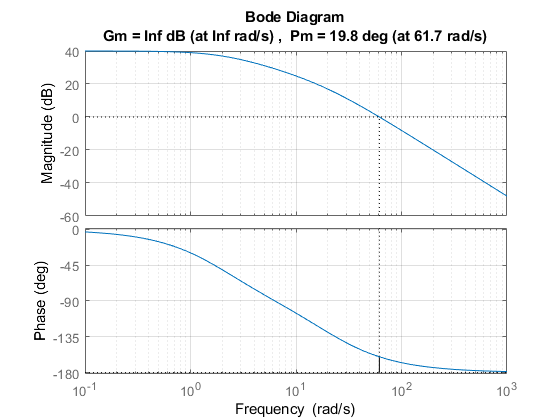

figure;margin(Kc*G);grid;

Para que a curva de módulo cruze por 0 dB na frequência wgl rad/s, o módulo deve ser reduzido em 20*log10(bode(Kc*G,wgl)).

Vamos escolher wgl=25rad/s para obter MF=45 graus.

wgl=25; % escolher valor
modulo=20*log10(bode(Kc*G,wgl))

modulo = 13.9475

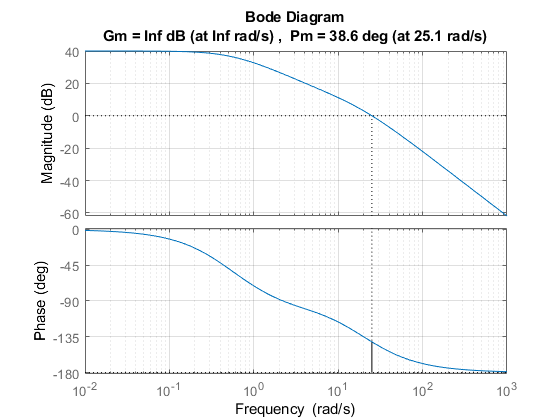

a=10^(-modulo/20);
T=10/(a*wgl);
C=tf(Kc*[a*T 1],[T 1]);
figure;
margin(C*G);grid;

Observa-se que a Margem de Fase obtida foi menor de 45 graus.

Deve-se especificar uma margem de fase desejada MFd sempre um pouco maior que a desejada. Pode-se observar no gráfico de Bode abaixo que a fase sempre atrasa um pouco em wgl devido ao atraso do polo em $s=-1/T$, de modo que não se consegue a MF o que foi especificada.

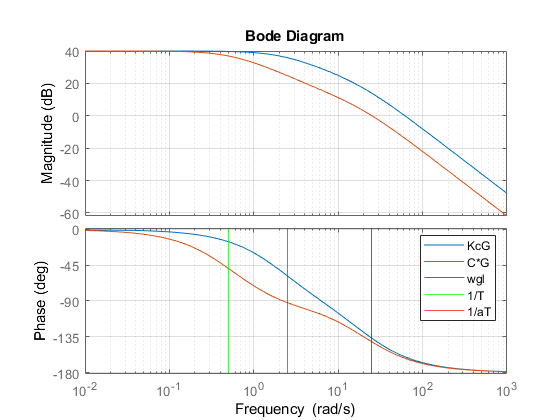

figure;bode(Kc*G,C*G);grid;
xline(wgl);
xline(1/T,'g');
xline(1/(a*T),'r');legend('KcG','C*G','wgl','1/T','1/aT');

**Usaremos agora a função atraso (projat). **

[c1,a1, T1]=projat(G,Kc,MFd);

Esta função executa os passos do projeto do compensador de atraso de fase.

Deve-se fornecer a FT G, o ganho Kc para atender o erro em regime, e a margem de fase desejada. 

A frequência onde ocorre o cruzamento da curva de módulo por 0dB (wgl) será calculada a partir dela. 

O valor de a1 é calculado encontrando o módulo que deve ser reduzido para passar por 0dB em wgl. 

Logo, a1=10^(-modulo/20), sendo  modulo= 20*log10(bode(Kc*G,wgl)).

T1 é calculado de modo que o polo esteja uma década antes de wgl. O compensador vem em c1, na forma $C_1(s)=K_c\frac{1+aTs}{1+Ts}$. 

Inicialização:

leg={};
UP=[];
MFD=[];
TS=[];
MF=[];
Y=[];
t=((1:1000)-1)/1000;
k1=1;

Varie o valor da margem de fase desejada MFd e observe o efeito na resposta ao degrau.

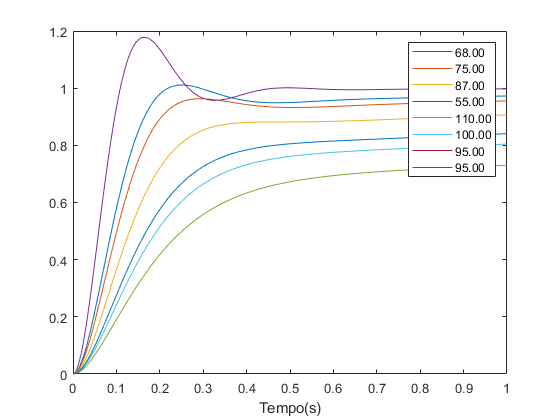

MFd=95; % Escolher valor
MFD=[MFD;MFd];
[C,a1, T1]=projat(G,Kc*20,MFd);
leg{k1}=num2str(MFd,'%3.2f');k1=k1+1;
M1=feedback(C*G,1);
y=step(M1,t);
Y=[Y y];
figure;
plot(t,Y);legend(leg);
xlabel('Tempo(s)');

S=stepinfo(M1);
UP=[UP; floor(S.Overshoot)];
TS=[TS; S.SettlingTime];
[~,mf]=margin(C*G);
MF=[MF; floor(mf)];
Tabela1=table(MFD,MF,UP,TS)

Tabela1 = 8×4 table
    MFD    MF     UP      TS   
    ___    ___    __    _______

     68     65     1     1.2893
     75     71     0     1.9309
     87     81     0     3.6612
     55     49    17    0.39513
    110    107     0     13.165
    100     97     0     8.1339
     95     91     0      6.311
     95     91     0      6.311


Recorde os valores especificados de UP e ts:

UPe

UPe = 4

tse

tse = 1

## Projeto do compensador avanço

O compensador avanço é dado por $C(s)=\frac{1}{a}\frac{1+aTs}{1+Ts}$, com $a>1$. 

Como o zero está em uma frequência mais baixa, $s=-1/aT$, ele avança a fase antes que o polo em $s=-1/T$ atrase a fase.

Para aumentar a margem de fase, a curva de fase deve ser aumentada próximo à frequência onde o módulo cruza em 0dB, de modo que a margem de fase atual mais a adicionada seja igual à desejada. 

O projeto do compensador atraso é mostrado na figura abaixo, para $a=10$ e $T=1$. 

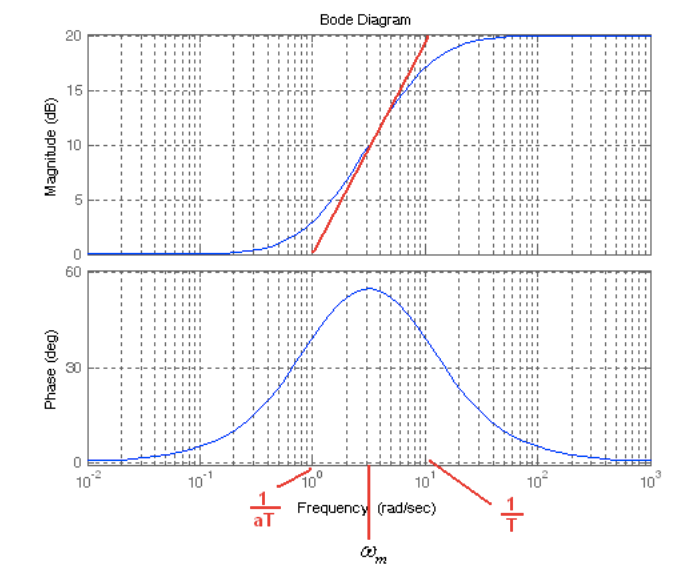					

O ganho começa com 0dB e atinge o máximo de 20dB. O valor máximo da fase do controlador é 55 . 				

O zero do controlador está em 1/aT=1rad/s. O polo está em 1/T=10rad/s. 

O ganho começa aumentar 20dB/dec a partir de 1rad/s (gráfico assintótico). 				

Nesta mesma frequência a fase já aumentou 45 graus. Em aproximadamente 10rad/s (polo) a inclinação da curva de módulo passa a ser 0, e a fase continua em 45graus, devido à fase somada pelo zero e subtraída pelo polo. Uma década após o polo (100rad/s), a fase volta a ser 0 graus e o módulo se mantém em 20dB. 

A frequência $\omega_m$ na qual o avanço de fase máximo é a média entre $1/aT$ e $1/T.$

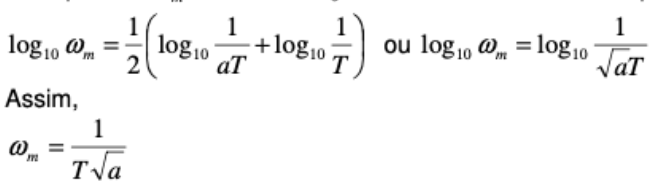

O avanço de fase $\phi_m$ é dado por

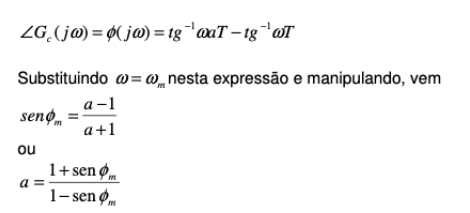

Módulo adicionado pelo controlador:

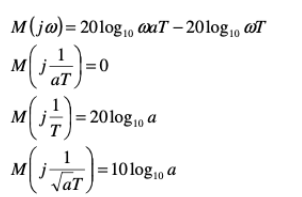

Logo, na frequência $\omega_m$ adiciona-se $\phi_m$ graus à margem de fase e $10log_{10}a$ ao módulo.

Usa-se o gráfico de Bode de malha aberta de Kc*g2 mostrado na Figura 3 para ver quanta fase deve ser adicionada.				

**Os passos de projeto são:**

1) Desenhe o gráfico de Bode com o ganho Kc para atender o erro em regime.

2) Verifique a fase $\phi_m$ que deve ser adicionada à curva de fase, de modo que $MF+\phi_m$ seja igual a MF', a margem de fase desejada.

3) Calcular **a** de $a=\frac{1+sen\phi_m}{1-sen\phi_m}$	

4) Verificar a quantidade de módulo adicionada pelo controlador, igual a $10log_{10}a$.

5) Obter do gráfico de Bode a frequência $\omega_m$ tal que $|G(j\omega_m)|=-10log_{10}a$.

6) Obter T de $T=\frac{1}{\omega_{m} \sqrt a}$.

**Problemas de projeto: **quando a fase a ser adicionada for grande, isto resulta em um valor de a também grande, o que pode inviabilizar o projeto deste controlador. 	  

O script a seguir executa estes passos de projeto, usando a FT Kc*G(s).

figure;margin(Kc*G);grid;

A margem de fase é 20 graus. Suponha que se deseje uma nova margem de fase de 45 graus.

Deve-se adicionar fi=25 graus.

fi=30; % escolher valor
fi1=fi*pi/180;
a=(1+sin(fi1))/(1-sin(fi1))

a = 3

modulo=10*log10(a)

modulo = 4.7712

wm=82; % rad/s
T=1/(wm*sqrt(a))

T = 0.0070

C=tf(Kc*[a*T 1],[T 1])

C =
 
   0.1056 s + 5
  --------------
  0.007041 s + 1
 
Continuous-time transfer function.



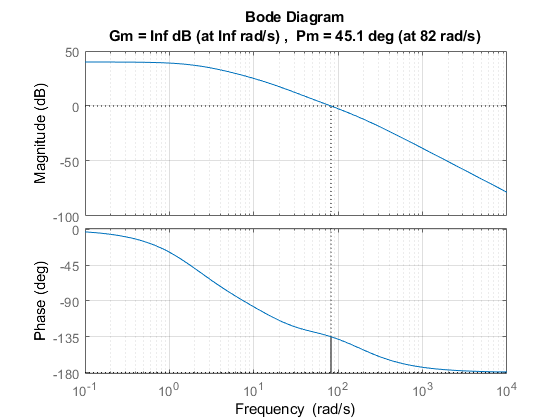

figure;margin(C*G);grid;

No gráfico de Bode abaixo observa-se que ao adicionar a fase $\phi_m$em $\omega_m=82 rad/s$, o módulo aumenta um pouco, cruzando 0dB um pouco mais à frente. 

Isso faz com que a Margem de Fase conseguida seja um pouco menor. Melhor aumentar um pouco mais  $\phi_m$.

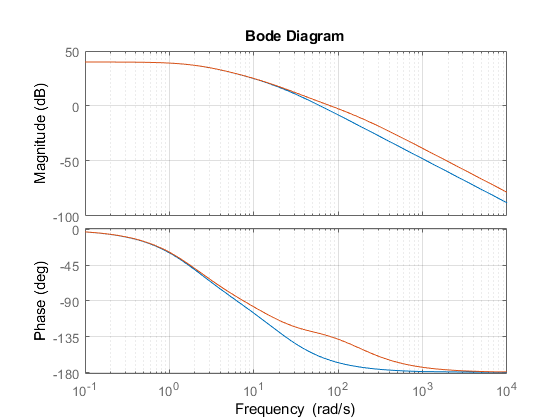

figure;bode(Kc*G,C*G);grid;

Vamos testar diferentes valores de $\phi_m$ e verificar seu efeito.

Inicialização:

leg={};
UP=[];
Wm=[];
TS=[];
MF=[];
A1=[];
Fi=[];
Y=[];
t=((1:1000)-1)/4000;
k1=1;

Escolha de diferentes valores de fi ($\phi_m$). Usaremos para isso a função projav.

[c1,a1, T1, wm]=projav(G,Kc,fi);

Esta função executa os passos do projeto do compensador de avanço de fase.

Deve se fornecer a FT G, o ganho Kc para atender o erro em regime, e a fase fi que se quer adicionar.

A função retorna o compensador na forma $C_1(s)=K_c\frac{1+aTs}{1+Ts}$ e a frequência wm na qual a fase fi foi adicionada.

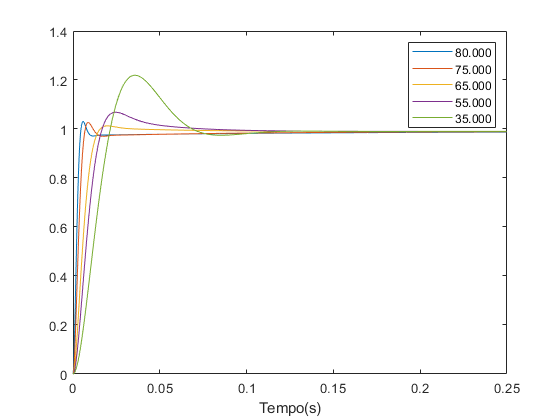

fi=35;% Escolher valores
[C1,a1, T1, wm]=projav(G,Kc,fi);
Fi=[Fi;fi];
Wm=[Wm;wm];
A1=[A1;a1];
leg{k1}=num2str(fi,'%4.3f');k1=k1+1;
M1=feedback(C1*G,1);
y=step(M1,t);
Y=[Y y];
figure;
plot(t,Y);legend(leg);
xlabel('Tempo(s)');

S=stepinfo(M1);
UP=[UP; floor(S.Overshoot)];
TS=[TS; S.SettlingTime];
[~,mf]=margin(C1*G);
MF=[MF; floor(mf)];
Tabela2=table(Fi,A1,Wm,MF,UP,TS)

Tabela2 = 5×6 table
    Fi      A1        Wm      MF    UP       TS    
    __    ______    ______    __    __    _________

    80    130.65    210.57    65     4    0.0073234
    75    57.695     154.2    65     3     0.017714
    65    20.346    131.95    70     2     0.023269
    55    10.059       100    64     7      0.05669
    35    3.6902    82.686    49    23     0.066346


Lembramos os valores especificados de UP e ts:

UPe

UPe = 4

tse

tse = 1

## Compensador avanço e atraso

Passos:

1) Projete o atraso para melhora a MF

2) Projete o avanço para melhorar a MF usando o projeto do atraso

3) Junte os dois compensadores

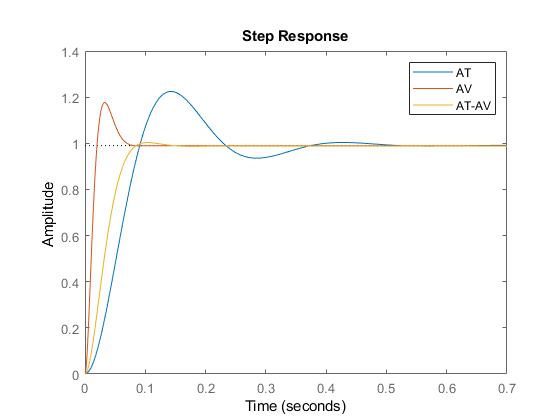

C1=projat(G,Kc,45);
C2=projav(G,Kc,40);
C21=projav(C1*G,1,35);
C3=C1*C21;
M1=feedback(C1*G,1);
M2=feedback(C2*G,1);
M3=feedback(C3*G,1);
figure;
step(M1,M2,M3);legend('AT','AV','AT-AV');

Claramente, o compensador avanço-atraso ficou melhor do que o avanço ou atraso sozinhos.